# 第一章 经典集和模糊集

IHR 的经典集表示

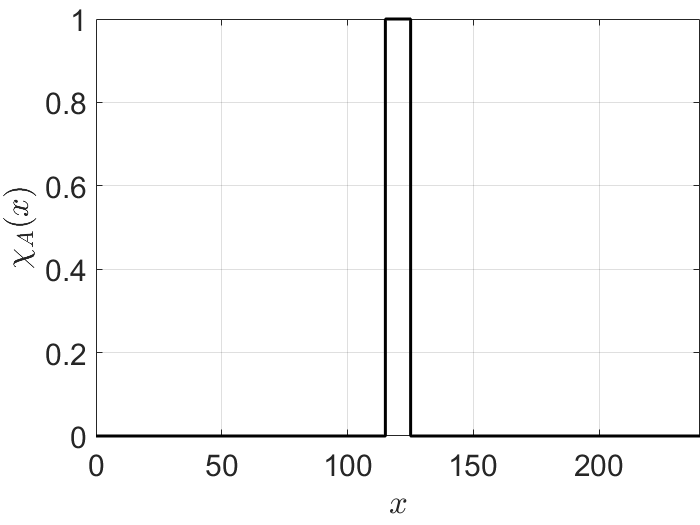

a = 120-5;
b = 120+5;
u = [0 a a 120 b b 240];
v = [0 0 1 1 1 0 0 ];
clf
plot(u,v,"LineWidth",1.8,"Color",'black')
%plot(u,v)
xticks=([0, 60, 120, 180, 240]);
xticklabels=({'0', '60', '120', '180' ,'240'});
ax = gca;
ax.FontSize = 18;
xlabel('$x$','Interpreter','latex')
ylabel('$\chi_A(x)$','Interpreter','latex')
ylim([0,1])
xlim([0,240])
%saveas(gcf,'impulse120.pdf')
ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];
grid on 
exportgraphics(gcf,'heart-120.pdf')

IHR 的模糊集表示

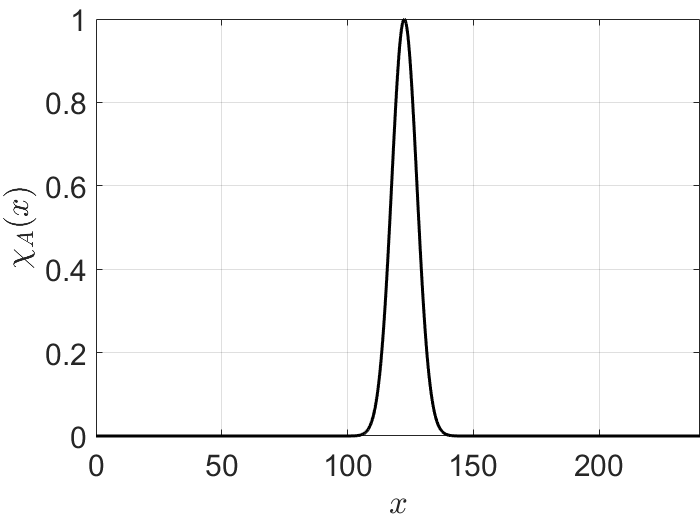

a = 120-5;
b = 120+5;
delta = 5;
c = 120+(delta)/2;
x = linspace(0,240,1000);
y = exp(-(x-c).^2/(2*delta.^2));

clf
plot(x,y,"LineWidth",1.8,"Color",'black')
%plot(u,v)
xticks=([0, 60, 120, 180, 240]);
xticklabels=({'0', '60', '120', '180' ,'240'});
ax = gca;
ax.FontSize = 18;
xlabel('$x$','Interpreter','latex')
ylabel('$\chi_A(x)$','Interpreter','latex')
ylim([0,1])
xlim([0,240])
%saveas(gcf,'impulse120.pdf')
ax = gca;
outerpos = ax.OuterPosition;
ti = ax.TightInset; 
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];
grid on 

exportgraphics(gcf,'heart-fuzzy.pdf')